**SISO Mixed Sensitivity with **$\mu$

Before we've solved with problem with mixed sensitivity synthesis, and did not achieve RP.  Let's now use $\mu \text{\,}$to fix that.

Build the model and generate the uncertainty weight as before.

m = ureal('m',2,'Range',[1,3]); 
k = ureal('k',100,'Percentage',20);
c = ureal('c',10,'PlusMinus',5);
G = tf(1,[m c k]);
Gvec = usample(G,100);
[P,info] = ucover(Gvec,G.NominalValue,4);
Wt = info.W1;  %Extract the weight

Now I'll maximize the crossover frequency with a standard first order sensitivity weight.

wh = 10;  %Just guessing at this...we'll see if it fails
wl = 0;
w_try = wh;  %Just for simplicity
w_new = 1/2*(wh+wl);
ii=1;
while(abs(w_new-w_try)>.01)  %Stopping criterion
    w_try = w_new;
    Wp = makeweight(1000,w_try,1/2);
    [K,CL,GAM(ii)] = mixsyn(G,Wp,[],Wt);  %Same synthesis
    S = 1-feedback(G*K,1);  
    perfmarg = robgain(Wp*S,1);  %Different analysis - this is quite similar to robuststab.  The "1" says that we're normalizing everything to 1 (the standard).
    mu(ii) = 1/perfmarg.UpperBound;
    %Just to compute mu for multiplicative uncertainty
    Smult = 1-feedback(P*K,1);
    perfmarg = robgain(Wp*Smult,1);
    mumult(ii) = 1/perfmarg.UpperBound;
    if mu(ii)<1
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
    ii=ii+1;
end

Now plot the achieved sensitivity functions for the uncertain plant vs the sensitivity weight.

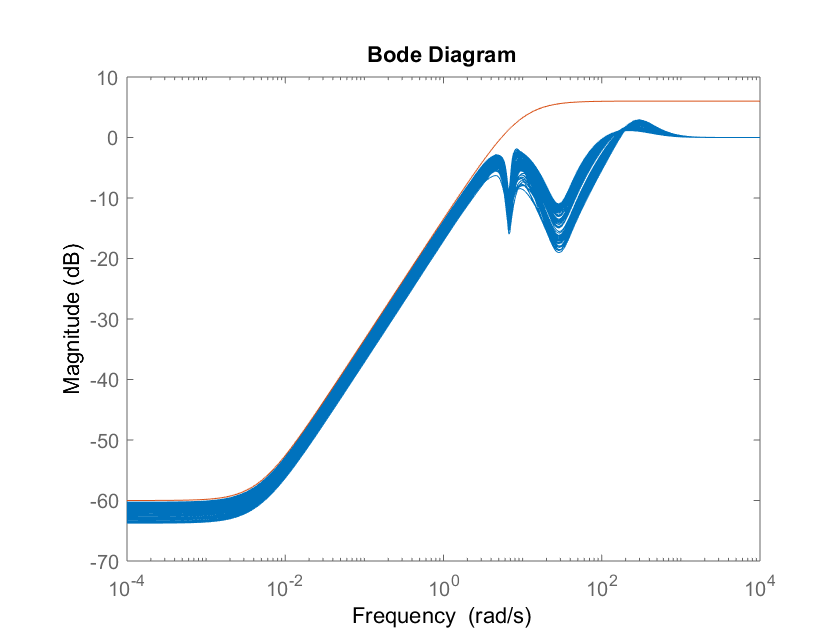

S = 1/(1+G*K);
Svec = usample(S,100);
bodemag(Svec,1/Wp)

This now does what we want!  We will now achieve robust performance for any combination of the three uncertain parameters.  Let's plot the singular values to see again why mixed sensitivity synthesis is not conservative.

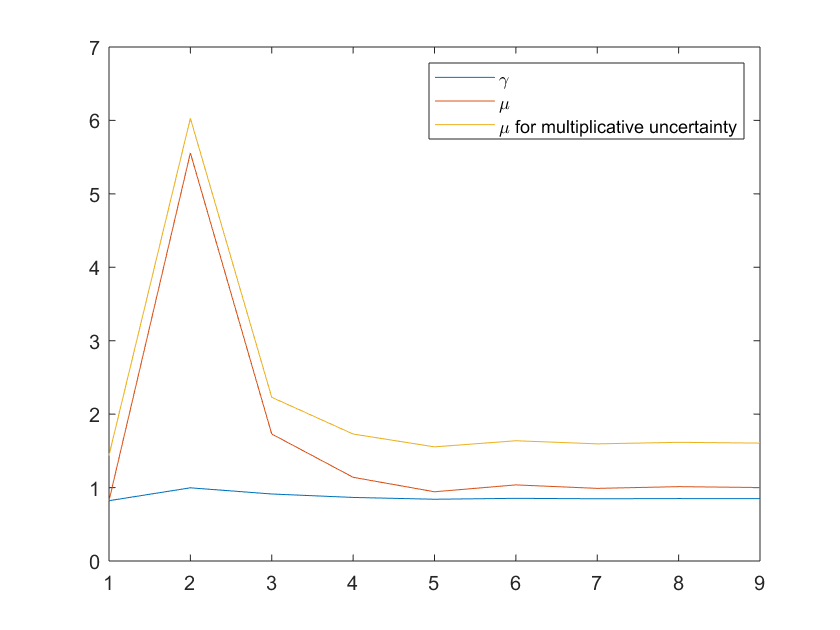

plot(1:length(GAM),[GAM' mu' mumult'])
legend('\gamma','\mu','\mu for multiplicative uncertainty')

It should be clear that the multiplicative approximation to the three real uncertain parameters was conservative.  In all cases mu for multiplicative uncertainty is within the promised $\sqrt{2}$ of gamma, but we do a bit better by using the actual structure of the uncertainty.

**Mu Synthesis**

One of many synthesis methods we will discuss is mu-synthesis, where we minimize mu instead of the infinity norm.  This is just a brief taste.  You will quickly see that this is much slower than *hinfsyn, *and has the same usage.

    %Form the generalized plant   
    Pmu = [Wp Wp*G;-1 -G];  %Mixed synthesis only considering Wp
    [Kmu,CLP,mu_mu] = dksyn(Pmu,1,1);  %Same usage as Hinfsyn
    mu_mu

mu_mu = 12.6664

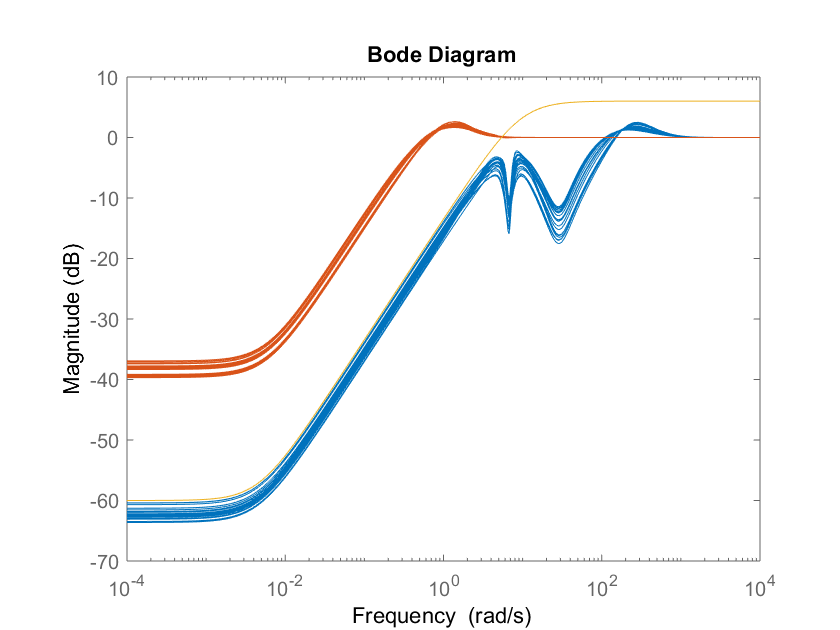

    Smu =inv(1+G*Kmu);
    bodemag(S,Smu,1/Wp)

Here mu-synthesis has failed us.  We already have an answer that is substantially better than this.  In fact, the first step of $H_{\infty }$ synthesis would certainlty provide a better result.

Pinf = [0 Wt*G;Wp Wp*G;-1 -G];  %Wrap uncertainty in
[Kinf,CL,gam] = hinfsyn(Pinf,1,1);
Sinf = 1/(1+G*Kinf);
perfmarg_inf = robgain(Wp*Sinf,1);
mu_inf = 1/perfmarg_inf.UpperBound

mu_inf = 1.0000

We can now use the $H_{\infty \text{\,}}$controller to help mu-synthesis along.  Below the option MixedMU let's the synthesis distinguish between real and complex uncertainty elements (default is all complex).

opt = dksynOptions('MixedMU','on','InitialController',Kinf);
[Kmu2,CLP,mu_mu2] = dksyn(Pmu,1,1,opt);
mu_mu2

mu_mu2 = 1.0000

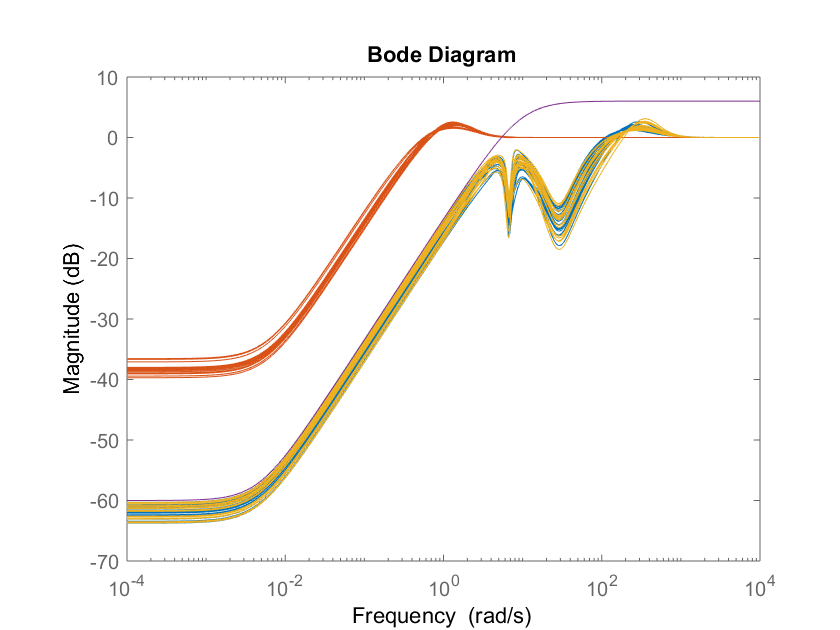

Smu2 = 1/(1+G*Kmu2);
bodemag(S,Smu,Smu2,1/Wp)

Obviously mu-synthesis should be used with care!  For this simple example, it is worse than $H_{\infty }$ synthesis.  Sometimes, especially for MIMO systems, it works well though!